# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments. The live script and the project report must be completed and delivered by **18.10.2024**

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 2`

This lab session covers mainly *synchronisation *in digital communication systems.

### `Digital Communiction System Schematic`

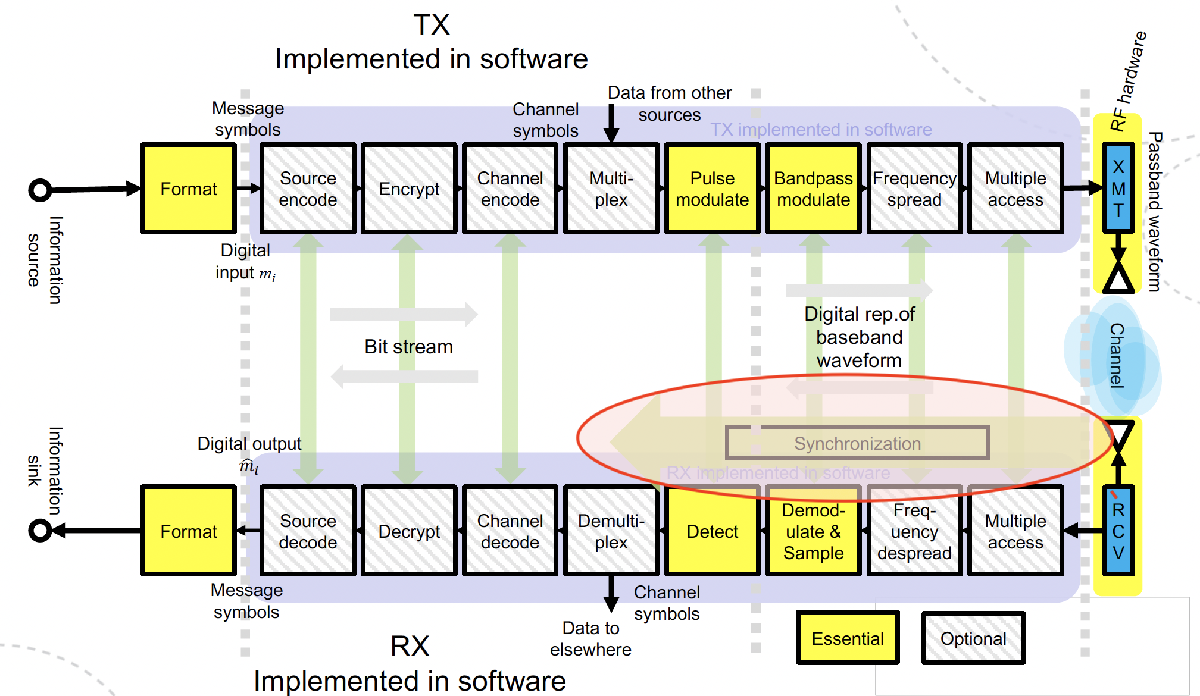

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

`Course Content`

- Synchronisation in digital communication systems

- Why synchronisation is needed ... 

- Channel and hardware effects 

#### `System Configuration (known from Project 1)`

% Symbol Rate 
symRate = 1000;         % 1/s



SNR = Simulink.Parameter(30)       % Signal to Noise ratio, specifically Energy per bit to Noise Power density ratio (Eb/No)

SNR =   Parameter with properties:

          Value: 30
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


Select modulation scheme

modScheme = "BPSK"

modScheme = "BPSK"




% For M-ary QAM specify modulation order (TODO: assert modOrder == 2/4 for modScheme == BPSK/QPSK)

modOrder = 2

modOrder = 2

Specify Transmit Filter Parameters

alpha =0.35  % Nyquist Filter Roll-Off Factor

alpha = 0.3500



filterLenSymbols = 10;            % Filter Length in Symbols


samplesPerSymbol = 8;             % Filter Upsampling Factor


################################# NEW  ##################################

% Specify the "virtual" carrier frequency 

fCRes = Simulink.Parameter(0);




% Phase Offset
phaseOffsets = Simulink.Parameter([0;pi/8;pi/4;pi/2;pi]);

phaseOffsetSelector  = Simulink.Parameter(1);


% Toggle Synchronisation Processes

toggleFLL = Simulink.Parameter(1); 

toggleTimingRecovery = Simulink.Parameter(1); 

togglePLL = Simulink.Parameter(1); 



`Task1 : Channel Effects`

**TODO: Provide more detail regarding the phase and frequency impairment model. **

Investigate which effects a phase offset ($\Delta \phi_{\textrm{LO}}$) and a frequency offset ($\Delta f_{LO}$ ) between the Tx and Rx local oscillator (LO) have on the received signal. Use the signal model for an analytic signal upconverted to passband

##                                 
$$s_+(t) = s(t) e^{j2\pi f_{c,tx}t}$$


which is mixed to baseband by a receiver LO with frequency $f_{c,Rx}=f_{c,Tx}+\Delta f$ and relative phase offset $\Delta \phi_{\textrm{LO}}$. In this task assume that $s(t)$ are downsampled complex symbols.

Considering the frequency and phase offset, then the received signal mixed to baseband can be rewritten as:

## 
$$s_+(t) = s(t) e^{j2\pi ((f_{c,rx}+\Delta f)t+\Delta \phi)} = s(t) e^{j2\pi t f_{c,rx}}e^{j2\pi t \Delta f}e^{j2\pi \Delta \phi}$$


% Investigate LO phase and freqeuncy offset on analytic baseband signal 

% Time of Frame including barker code (barker code is technically only needed for last exercise)
time = (0:1/symRate:1-1/symRate+1/symRate * 13)'; 
time

time =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090
    0.0100
    0.0110
    0.0120
    0.0130
    0.0140


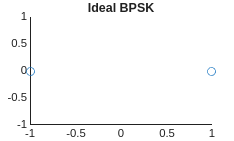

% Generate Tx message symbols
Nmsg = 30;
% QPSK:
%bitsI = randi([0 1], Nmsg, 1);
%bitsQ = randi([0 1], Nmsg, 1);
%symTx_msg = (2*bitsI - 1) + 1j*(2*bitsQ - 1);
%symTx_msg = symTx_msg / sqrt(2);
% BPSK:
bitsI = randi([0 1], Nmsg, 1);

barker_code = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1];
symTx_msg = 2*bitsI - 1;

symTx = [barker_code';symTx_msg];


% Define a Tx frequency
fc_Tx = 20e3; %transmitt on 20 khz

% Plot Tx symbols
figure;
scatter(symTx,zeros(length(symTx)))
title('Ideal BPSK')


% Generate real and imaginary parts of the noise
standard_dev = 0.1;
len_sym = length(symTx);
Noise_R = standard_dev * randn(size(symTx));
Noise_I = standard_dev * randn(size(symTx));
% By default, randn considers mean 0 and variance 1 (and of course, power 1)

% Combine them to create complex Gaussian noise
Noise_Complex = Noise_R + (1j * Noise_I);
Noise_Complex

Noise_Complex =    0.0888 + 0.0889i
  -0.1147 - 0.0765i
  -0.1069 - 0.1402i
  -0.0809 - 0.1422i
  -0.2944 + 0.0488i
   0.1438 - 0.0177i
   0.0325 - 0.0196i
  -0.0755 + 0.1419i
   0.1370 + 0.0292i
  -0.1712 + 0.0198i
  -0.0102 + 0.1588i
  -0.0241 - 0.0804i
   0.0319 + 0.0697i
   0.0313 + 0.0835i
  -0.0865 - 0.0244i


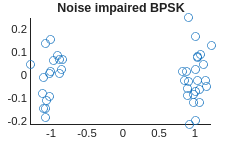


%Noise_C = 1/sqrt(2)*(Noise_R + Noise_I);
% Real and Imaginary noise have energy 1, so we divide by sqrt(2) to obtain
% unit energy in the Complex Noise.

% Impair Tx signal with noise
Tx_signal = symTx + Noise_Complex;
figure
scatter(real(Tx_signal), imag(Tx_signal));
title('Noise impaired BPSK')

Tx_signal

Tx_signal =   -0.9112 + 0.0889i
  -1.1147 - 0.0765i
  -1.1069 - 0.1402i
  -1.0809 - 0.1422i
  -1.2944 + 0.0488i
   1.1438 - 0.0177i
   1.0325 - 0.0196i
  -1.0755 + 0.1419i
  -0.8630 + 0.0292i
   0.8288 + 0.0198i
  -1.0102 + 0.1588i
   0.9759 - 0.0804i
  -0.9681 + 0.0697i
   1.0313 + 0.0835i
   0.9135 - 0.0244i


% Since fc_Tx takes values in -1 and 1, its total power is equal to its
% length. Same for Noise_C, since the variance is 1 per each bit:
%fc_Tx = fc_Tx + (1/SNR.Value)*Noise_C;

% Upconversion (using padding) aka upsampling ?
fc_Tx_upconv = upsample(Tx_signal, samplesPerSymbol);
fc_Tx_upconv

fc_Tx_upconv =   -0.9112 + 0.0889i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.1147 - 0.0765i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i




% Implement phase and frequency impairments resulting from LO offset
%time2 = linspace(0,symRate*length(symTx)+samplesPerSymbol,length(fc_Tx_upconv))';
%fc_Rx = exp(1j*2*pi*phaseOffsets.Value(phaseOffsetSelector.Value)) * fc_Tx_upconv .* exp(1j*2*pi*fCRes.Value.*time2);
Ns = length(fc_Tx_upconv);%number of samples
Fs = symRate * samplesPerSymbol;%sampling frequenzy
t = (0:Ns-1)'/Fs;
t

t =          0
    0.0001
    0.0003
    0.0004
    0.0005
    0.0006
    0.0008
    0.0009
    0.0010
    0.0011
    0.0013
    0.0014
    0.0015
    0.0016
    0.0018


%make normally distributed phase and freq offset
phase_std = 0.2;
freq_std = 10;
phaseOffset = phase_std * randn;%creates one random number
freqOffset = freq_std * randn;

fc_Tx_impaired = fc_Tx_upconv .* exp(1j * (2*pi* freqOffset*t + phaseOffset))

fc_Tx_impaired =   -0.8990 - 0.1730i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.0872 - 0.2576i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


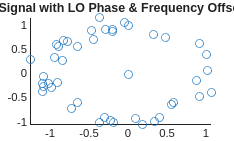


figure;
scatter(real(fc_Tx_impaired), imag(fc_Tx_impaired));
title('Signal with LO Phase & Frequency Offset');

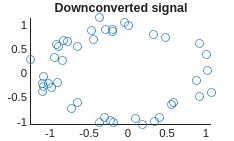


%send over to reciever
fc_Rx = fc_Tx_impaired;

% Downconvert signal to baseband
sigDC = zeros(length(fc_Tx_upconv)/samplesPerSymbol,1);%downconverted
for i=0:length(fc_Rx)/samplesPerSymbol-1
    sigDC(i+1) = fc_Rx(i*samplesPerSymbol+1);
end

% Plot received symbols

figure;
scatter(real(sigDC), imag(sigDC))
title('Downconverted signal')

`Task 2 : Synchronisation Effects`

Synchronisation in (digital) communication systems aims for removing the phase and frequency effects and impairments discussed above. The simulink model contains blocks on the receiver end of the communication link that implement the following crucial synchronisation steps:

- Coarse Frequency Correction with e.g., **Frequency-Locked Loop (FLL) **(Matlab uses corrrelation and FFT based methodss)

- Timing Offset Correction with a **Symbol Synchronizer **

- Residual Frequency Offset Correction and Phase Sychronisation with a **Phase-Locked Loop (FLL)**

**Toggle the different synchronisation steps and observe the resulting signal characterisitcs (eye diagram, constellation diagram, signal spectrum) in each case. Explain the observations and argue mathematically where you see fit. **

`Task 3 : Implementation of a Costas-Loop (data-free synchronization)`

 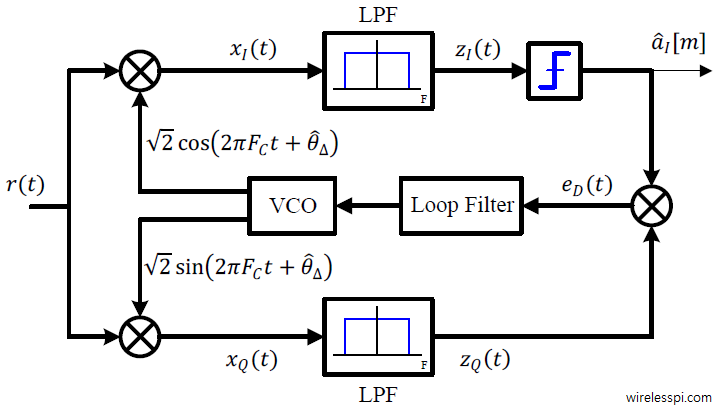

The illustration above shows the principle architecture of a *Costas Loop* for a **BPSK** receiver architecture (**NB! The illustration above treats a passband signal; our system operates on a *****complex baseband  signal***). The Costas loop is a variation of the traditional PLL that uses the IQ demodulation principles to lock onto the phase (and frequency) of a signal. 

The first step in the processing chain is the generation of the error signal $e_D$ which measures the phase difference between the reference sinusoid and the input signal. 

The *loop filter *is an integral part of the PLL. The design of the loop filter largely determines the performance characteristics of the PLL. The loop filter follows the basic structure

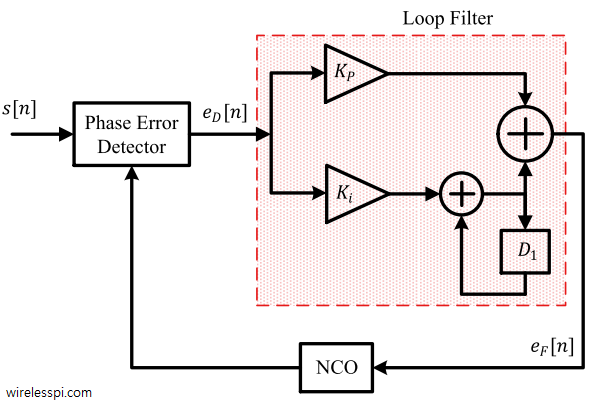

with appropriate filter coefficients $K_p
$ and $K_i$. (The *D1 *block is a one-step time-delay)

The generated and loop filtered *error signal *$e_F$ serves as input to a *Numerically Controlled Cscillator* (NCO).The NCO adjusts the phase of the generated sinusoid as

                                                             
$$\phi_{NCO}\leftarrow\phi_{NCO}+K_0e_F$$


where $K_0$ is the gain of the NCO. This essentially constitutes an integration or accumulation. 

Imlement the Costas Loop and enable your function in the simulink dashboard. Test the Costas Loop implementation first with the test signal you generated in *Task 1*. You can use the loop parameters defined in the function body. You are welcome to experiment with different parameter values; the loop parameter largely determine the the Costas loop performance, so it is interesting to observe how changes in parameters impact the outcome. 

**NB! Make sure that *****modScheme = "BPSK" *****when testing the function in the Simulink model. **

%costasLoop(...);  %

% Run the Simulink model  
%out = sim("CommSysSimulink_Project2.slx",'StopTime','inf');

% Implementation of Costas Loop
% Implementation is done in the complex regime
function symOut = costasLoop(symIn)
    % Loop Filter
    Kp = 0.1;
    Ki = 0.1;

    % NCO Gain
    Ko = 1.5;

    %preset correctiong phase and freq currently zero error
    %need to be persistant variables to keep memory between calls
    persistent phase_error;
    persistent freq_error;

    if isempty(phase_error)
        phase_error = 0
    end
    if isempty(freq_error)
        freq_error = 0
    end 

    % Implement Costas Loop

   % have to rotate symIn based on prewious knowlage
   symOut = Ko*(symIn * exp(1j*-phase_error));

   %seperating I and Q
   I = real(symIn);
   Q = imag(symIn);
    
   %this gives the sign and magnitude of small errors caused by
   %rotation only works for BPSK as everythong that gives values are
   %errors
   error = I*Q;

   freq_error = freq_error + Ki*error;
   phase_error = wrapTo2Pi(phase_error + freq_error + Kp*error);

end

`Task 4 : Data-aided synchronization`

We can make use of the *known *frame synchronisation sequence (preamble) to estimate the phase and frequency offset in the received symbols. Implement a function that estimates $\Delta\phi_{LO} $ and $\Delta f_{LO}$ from the recieved input signal. Use the estimated values to synchronize the received symbols. 

**NB! If you want to try integrating data-aided synchronisation into the Simulink model, note that the known Barker code preamble has an offset of ****10 samples ****from the start of the input sequence *****symIn*****. For application in the Simulink model, the CFO estimation needs to account for noise in the CFO estimation across frames. For this purpose the following code snippet is included in the function below**

*Can you explain this?*

% Implement a function that uses the known preamble sequence to estimate
% phase and frequency offset in the received symbol stream
% Tip: Test your function with your simulation data from task 1

% syncedData = dataAidedSync(sigDC)

% Plotting the synchronized data


 out = sim("CommSysSimulink_Project2_SOLUTION.slx",'StopTime','inf')
% dataAidedSync(testSym.')

function syncdSymOut = dataAidedSync(symIn)

% symIn: preamble sequence + data symbols

% For use in Simulink model 
% persistent cfo_est 
% alpha = 0.7;
% 
%     if isempty(cfo_est)
%         cfo_est = 0;
%     end

preamble = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1].';

r_preamb = symIn(11:length(preamble)+10);


phaseCorrSeq = r_preamb .* conj(preamble);


phase = angle(phaseCorrSeq);

% You can plot the phase to get an intution 


% Use the functiomn movemean() to lowpass filter the extracted phase
phase = movmean(phase,6);


% Phase offset
phi0 = phase(1);


% Estimate frequency offset


% For Simulink model use: 
% cfo_est = estmP(1)*alpha * (1-alpha)*cfo_est


% Rotate Data to compensate for phase and frequency offset
% NB! For use in the simulink model (again) remember that there is a sample
% offset of 10 samples before the preamble starts (due to application
% specific reasons) 



end
